## **CHARLESŮV ZÁKON**

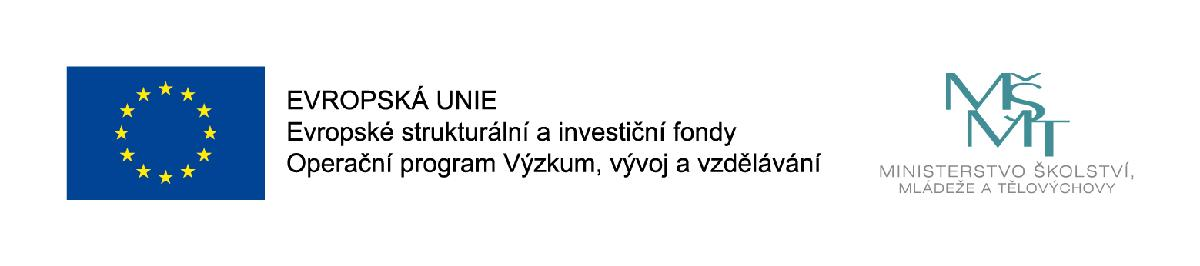

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

Charles (1746-1823) sledoval chování plynu za konstantního objemu. 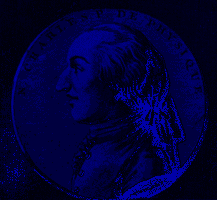

**Slovní formulace: **

Za konstantního objemu roste tlak plynu lineárně s teplotou. Hodnota rozpínavosti $$\beta$$ je pro všechny plyny stejná.

**Matematická formulace:**

$\[p = {p_o}(1 + \beta  \cdot t)\]$    $p_{o}$   tlak při  $t_{o} = 0 °C$ $\beta = 1 / 273,15  K^{-1}$

**Po úpravě: **


$$\[p = {p_o} \cdot \left( {1 + \frac{1}{{273,15}} \cdot t} \right) = \frac{{{p_o}}}{{273,15}} \cdot \left( {273,15 + t} \right) = \frac{{{p_o}}}{{{T_o}}} \cdot T\]$$


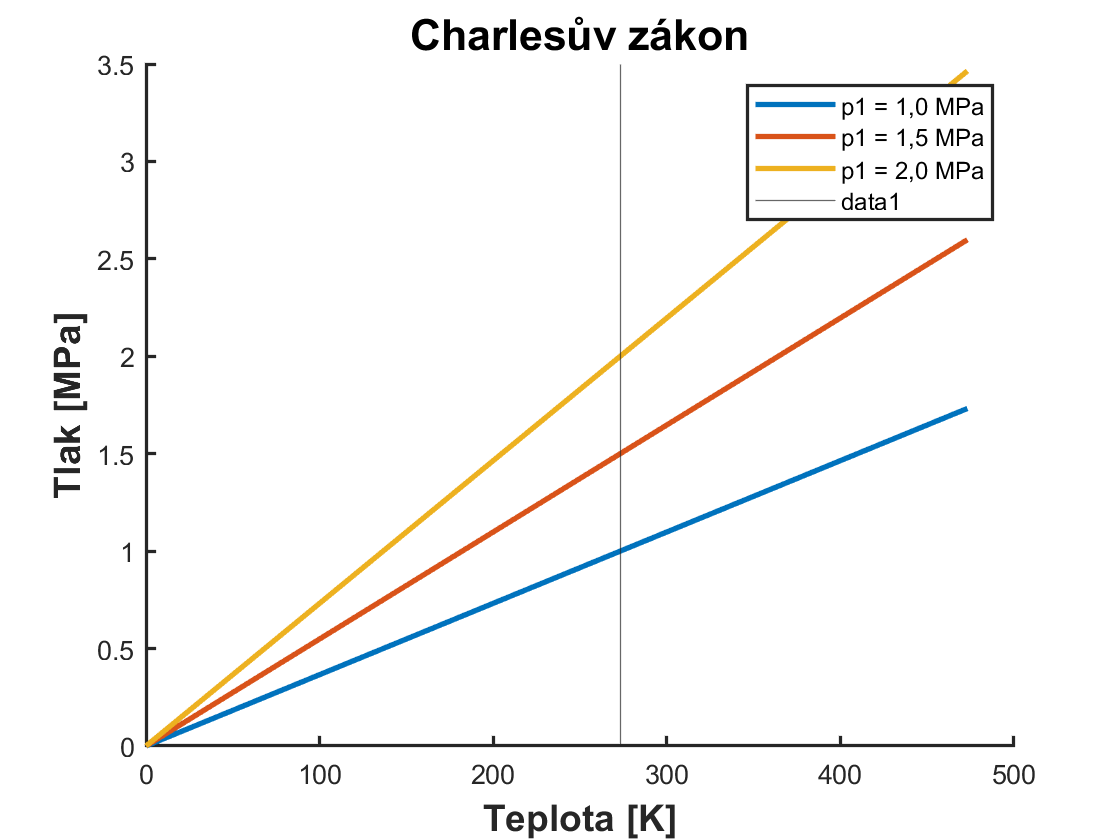

p0_1 = 1.0*MPa;
T0 = 273.15;
T(1) = 0;
p(1) = p0_1/T0*T(1)/MPa;
T(2) = 263.15;
p(2) = p0_1/T0*T(2)/MPa;
T(3) = 373.15;
p(3) = p0_1/T0*T(3)/MPa;
T(4) = 473.15;
p(4) = p0_1/T0*T(4)/MPa;
hold on;
plot(T,p,'-','linewidth',2);
p0_1 = 1.5*MPa;
T0 = 273.15;
T(1) = 0;
p(1) = p0_1/T0*T(1)/MPa;
T(2) = 263.15;
p(2) = p0_1/T0*T(2)/MPa;
T(3) = 373.15;
p(3) = p0_1/T0*T(3)/MPa;
T(4) = 473.15;
p(4) = p0_1/T0*T(4)/MPa;
plot(T,p,'-','linewidth',2);
p0_1 = 2.0*MPa;
T0 = 273.15;
T(1) = 0;
p(1) = p0_1/T0*T(1)/MPa;
T(2) = 263.15;
p(2) = p0_1/T0*T(2)/MPa;
T(3) = 373.15;
p(3) = p0_1/T0*T(3)/MPa;
T(4) = 473.15;
p(4) = p0_1/T0*T(4)/MPa;
plot(T,p,'-','linewidth',2);
hold off;
title('Charlesův zákon','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Teplota [K]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Tlak [MPa]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
%xlim([1 15]);
%ylim([0 1]);
%grid on;
set(gca, 'linewidth',1.2);
legend('p1 = 1,0 MPa','p1 = 1,5 MPa','p1 = 2,0 MPa')
xline(273.15);

Závislost změny tlaku na změně teploty, při konstantním objemu a závislost změny objemu vlivem teploty při konstantním tlaku, stanovili r. 1787 *Charles *(1746—1823), r. 1801 *Dalton *(1776—1844), r. 1802 *Gay-**Lussac* (1778 až 1850).

Měření ukázalo, že ohříváním plynu za stálého tlaku se jeho objem zvětšuje stejně a rovnoměrně. Při ohřátí o 1 °C se zvětší objem plynu o hodnotu,kde *v**0* je objem plynu za normálního stavu *t = *0 °C a *p = *101325 Pa.

Podobná závislost byla nalezena pro ohřívání plynu za stálého objemu. Tlak plynu za stálého objemu roste stejně a rovnoměrně. Při ohřátí o 1 °C stoupne tlak o hodnotu

O stejné hodnoty ubývá objem nebo tlak za konstantního tlaku nebo objemu při ochlazování plynu. Na základě extrapolace výsledků měření předpokládáme, že při izobarickém ochlazení plynu z teploty 0 °C na teplotu **-**273,15 °C bude objem ideálního plynu roven nule. Poněvadž není možno si představit záporný objem, znamená to, že teplota -273,15 °C je pravděpodobně nejnižší dosaži­telná teplota. Tato nejnižší tep­lota se nazývá *absolutní nula. *Teplota měřená od absolutní nuly se nazývá *absolutní tep­lota *a označujeme ji na rozdíl od teploty měřené od $t_0=0\; °C$, tj. teploty tání ledu, $T_0=0\;K$ (Kelvin). 

### Příklad

Monopost formule 1 optimálně pracuje, pokud má teplotu pneumatik 92 °C a tlak 240 kPa. Na jaký tlak musí mechanik pneumatiky nahustit, pokud v době huštění mají pneumatiky teplotu 22 °C. Atmosférický tlak v době huštění je 1010 hPa, kdežto při závodě se předpokládá atmosferický tlak 990 hPa.

Doplňujicí otázky:

Závisí huštení na objemu pneumatiky?

Má na to vliv druh plynu?

to = 92.0;          % °C
po = 240*kPa;       % kPa
th = 22.0;          % °C
pbh = 1010*hPa;     % hPa
pbo = 990* hPa;     % hPa

Absolutní teploty a tlaky

To = C2K(to);
Th = C2K(th);
poa = po + pbo;

Výpočet

pha = poa*Th/To;
ph = pha - pbh;
fprintf('Tlak na, který je třeba hustit je  %.3f kPa\n',ph/kPa);

Tlak na, který je třeba hustit je  173.013 kPa


Výsledný tlak je nezávislý na velikosti pneumatiky a plynu, kterým byla nahuštěna.

# Funkce

function [res] = MPa
res = 10000000.0;
end
function [res] = kPa
res = 1000.0;
end
function [res] = hPa
res = 100.0;
end
function [K] = C2K(C)
% Convert temperature from degrees Celsius to Kelvin.
K = C+273.15;
end
function [C] = K2C(K)
% Convert temperature from Kelvin to degrees Celsius.
C = K-273.15;
end